# Notebook 4: Stocks and Flows, SIR

*Author:* Zachary del Rosario, Fall 2020

*Learning Objectives:* As a result of working through this notebook, you will learn:

- The concepts of **stocks** and **flows**

- How to **model** physical systems with stocks and flows

- An example stock and flow model in the context of [epidemiology](https://en.wikipedia.org/wiki/Epidemiology) (study of disease transmission); the SIR model

- How to relate a stock and flow model to a set of *evolution *equations

- How to implement a stock and flow model in code

## Stocks and Flows

[Stocks and flows](https://en.wikipedia.org/wiki/Stock_and_flow) are a conceptual toolkit for understanding models.

- A **stock** is a collection of some "stuff"

- A **flow** is a means for "stuff" to flow from one stock to another

The stock and flow concept draws on a water analogy: Imagine buckets connected by pipes. The water represents "some stuff"---it could be money, energy, heat, Pokemon cards, etc. Each stock represents a place that "stuff" could sit; for instance, with money our stocks could be banks and businesses. Flows represent how "stuff" can flow between stocks; for instance, with money the flows could represent loans, which transfer money from banks to businesses.

Part of the power of the stock and flow concept is how general it is. But that also makes it difficult to grasp without some concrete example. So let's look at an example!

### The SIR Model

As a concrete example, let's think about a stock and flow diagram depicting disease transmission. The following diagram depicts the "SIR model", which stands for "**S**usceptible, **I**nfectious, **R**ecovered". 

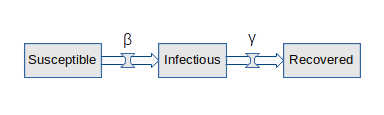

Each box is a stock, and each arrow is a flow. Note that each arrow also has a small "valve"; this represents some physical mechanism that controls the rate of flow. Each valve also has a parameter that describes the physical mechanism. 

Our three stocks are:

- **Susceptible**: The number of persons that could still get infected by the disease

- **Infectious**: The number of persons currently infected with the disease, capable of spreading the disease to others

- **Recovered**: The number of persons who have recovered from the disease, no longer capable of infecting others

These three stocks are connected by two flows:

- **Infections**, controlled by the $\beta$ valve. This moves persons from S to I. This flow describes how quickly the disease tends to move through the population.

- **Recoveries**, controlled by the $\gamma$ valve. This moves persoms from I to R. This flow describes how quickly each infected person tends to recover from the disease.

This picture is *useful*, in that it makes some of our modeling assumptions explicit through a picture. *For instance*, the SIR model above assumes that recovered persons cannot become re-infected; this may be a good assumption for a disease like chickenpox, where [reinfection is rare](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC4529600/). It may be a bad assumption for other diseases.

**Exercise:** Based on the SIR stock and flow diagram above, could we "play" with the valves to represent public health interventions meant to reduce the rate of spread of the disease? Which valve would we "play" with to represent that change?

*(Write your answer here)*

*Solution:* Yes, we would "play" with the $\beta$ valve to represent public health interventions targeting the spread of the disease.

This picture is *not complete*, in that it doesn't tell us everything we might like to know about the model. For instance, how exactly does $\beta$ determine the rate of infection? To answer that, we'll need to relate the stock and flow diagram to a set of equations.

## Translating SIR to Equations

The SIR stock and flow diagram gives us a useful picture to reason about the model, but it does not give us all the details we would need to run simulations. To do that, we need to *translate* this stock and flow diagram into a set of equations. In so doing, we'll find that we need to add a bit more detail to the model.

First, let's introduce *state variables* to represent each of the three stocks:


$$S_t = \text{Count of Susceptible persons at time } t \\
I_t = \text{Count of Infectious persons at time } t \\
R_t = \text{Count of Recovered persons at time } t $$


*Note*: This already introduces something not explicitly represented in our diagram above; adding the $t$ subscripts makes time explicit.

Let's also introduce variables to represent the two flows:


$$\Delta I_t = \text{Number of Infections at time } t \\
\Delta R_t = \text{Number of Recoveries at time } t$$


Great! Now we have some mathematical shorthand for referring to the stocks and flows. To do useful work with this math, we'll need to define how these symbols relate. To do that, we'll define a set of *evolution equations*.

### Evolution equations

An *evolution equation* is a fancy term that just tells us how a quantity changes in time ("evolves"). For instance, the following would be an (unrealistic) evolution equation for the SIR model:


$$\text{(Note: This is unrealistic!)} \\
I_{t+1} = I_t + 1$$


This (unrealistic) evolution equation simply states that, at each point in time the next state $I_{t+1}$ is related to the previous state $I_t$ plus one additional infected person. There's no reason this should be happening: It's our responsibility as modelers to write down math that *reasonably* represents reality.

First, let's start with a super-basic model that's not "going" anywhere:


$$\text{(Note: This model assumes no flows)} \\
S_{t+1} = S_t \\
I_{t+1} = I_t \\
R_{t+1} = R_t$$


This would be a stock diagram with no flows: Each state is constant in time. Next, let's add the Infections flow. We might start by just adding the Infections to the Infected category:


$$\text{(Note: This model is wrong!)} \\
S_{t+1} = S_t \\
I_{t+1} = I_t + \Delta I_t \\
R_{t+1} = R_t$$


But where did these Infected people come from? In order for this stock and flow model to make sense, each of the Infected persons need to *move from one stock to another*. For the Infections flow, persons move from Susceptible to Infected; if we add to Infected, we need to subtract the same value from Susceptible


$$\text{(Note: This model has the Infections flow only)} \\
S_{t+1} = S_t - \Delta I_t \\
I_{t+1} = I_t + \Delta I_t \\
R_{t+1} = R_t$$


**Protip:** When you're building a stock and flow diagram, make sure each $\Delta$ term is *added* to one stock and *subtracted* from another. Otherwise you'll have a "leaky" model!

**Exercise:** Now it's your turn! Modify the evolution equations to include the Recovered flow $\Delta R_t$.

*(Solution)*


$$\text{(Note: This model is correct!)} \\
S_{t+1} = S_t - \Delta I_t \\
I_{t+1} = I_t + \Delta I_t - \Delta R_t \\
R_{t+1} = R_t + \Delta R_t$$


### Modeling the Flows

We've defined *which *flows connect which stocks, but we haven't yet described *how *those flows behave. Put differently, how do we compute $\Delta I_t, \Delta R_t$? We'll need to *model *those terms.

### Modeling Recoveries

What factors do Recoveries depend on? Clearly, if there are no infected persons, then there should be no recoveries---there's no one to recover! Thus, recoveries should probably depend on the number of infected persons $I_t$. 

It doesn't seem like $R_t$ should enter---once a person has recovered they don't "recover again." 

The Recovery flow connects $I_t$ to $R_t$; while there are some ways I could imagine moving persons from $S_t$ to $R_t$, that would have to be in a different flow. Thus the term $S_t$ can't reasonably show up in our Recovery flow.

Based on this reasoning, let's define a simple proportional model for $\Delta R_t$:


$$\Delta R_t = \gamma \times I_t$$


Here I'm using $\gamma$ to match the stock and flow diagram above; this *constant of proportionality* gives us a way to "tune" the model.

**Physical meaning of **$\gamma$: Since the Recoveries flow is based on the number of infected persons $I_t$ and the model is marching forward in time, the $\gamma$ constant represents the *recovery period*; for instance, if $\gamma = 1 / 4$ then "one quarter" of a person will move from Infected to Recovered each step of $t$. If $t$ represents weeks, then $\gamma = 1 / 4$ would mean a recovery period of 4 weeks.

**Exercise:** Can you think of a *physical* reason why persons from $S_t$ could flow into the number of recovered persons $R_t$? What additional flow would you need to add to the stock and flow diagram (i.e. what two boxes would you connect)?

*(Solution:)* This is just one example: Susceptible persons could flow to "Recovered" by immunization; this would allow them to skip the Infectious period. We could add a flow from $S_t$ to $R_t$ to model this public health intervention.

### Modeling Infections

What factors do Infections depend on? Clearly we need people Susceptible to the disease in order for infections to occur, so $S_t$ should enter into $\Delta I_t$. However, we also need some way for the disease to spread. Infectious persons are, by definition, infectious, so $I_t$ should enter into $\Delta I_t$ as well.

Recovered persons---in the SIR model---are not infectious. Note that some diseases, such as HIV, can be transmitted by persons not showing symptoms: The SIR model we have defined here is *not* a good model for this kind of disease transmission. Based on the stock and flow model defined above $R_t$ should not affect the $\Delta I_t$ term.

Based on this reasoning, we can define another proportional model for Infections


$$\Delta I_t = \beta \times I_t \times S_t$$


**Physical meaning of **$\beta$: Since the Infections flow is based on the number of both infected persons $I_t$ and susceptible persons $S_t$, and the model is marching forward in time, the $\beta$ constant represents the *transmission rate *from infected to susceptible persons*.*

**Exercise:** Let's suppose $\beta = 1 / 50, S_1 = 50, I_1 = 1$. What would $\Delta I_t$ be equal to *in our model?* *In reality*, would you expect $\Delta I_t$ to *always* take the same value given $S_1 = 50, I_1 = 1$? Why or why not? What kind of simplifications does this model make?

*Hint:* Are all human beings identical? What about people of different ages?

*Solution:* I would *not* expect $\Delta I_t$ to take the same fixed value for all persons. This model treats all persons as equally likely to transmit or be infected, and treats the disease itself as fixed in transmissivity. There is likely to be variability in susceptibility across persons; for example, older folks and those with a suppressed immune system are more susceptible to contracting a disease.

In summary, the flows are modeled by:


$$\Delta I_t = \beta \times I_t \times S_t \\
\Delta R_t = \gamma \times I_t
$$


We've completed the *conceptual* steps of building the model: creating a stock and flow diagram and making modeling choices for the flows. Now we need to *implement* the model in code.

## Implementing the SIR Model

In summary, our SIR model evolution equations are:


$$\Delta I_t = \beta \times I_t \times S_t \\
\Delta R_t = \gamma \times I_t \\
S_{t+1} = S_t - \Delta I_t \\
I_{t+1} = I_t + \Delta I_t - \Delta R_t \\
R_{t+1} = R_t + \Delta R_t$$


Like the bikeshare model, we can implement this model by creating variables `s, i, r` to track the state and running an update script. *However*, we're going to use a concept from Chapter 5 of the Robot Book and encapsulate the update step of our model in a *function*.

### A Function Implementation

The following code is contained in the file `sir_step.m`; I've copied it below for convenience. 

%% NOTE: No need to edit this code; it's contained in the file `sir_step.m`
% function [s_n, i_n, r_n] = sir_step(s, i, r, beta, gamma)
% % fcn_step Advance an SIR model one timestep
% %
% % Usage
% %   [s_n, i_n, r_n] = fcn_step(s, i, r, beta, gamma)
% % 
% % Arguments
% %   s = current number of susceptible individuals
% %   i = current number of infected individuals
% %   r = current number of recovered individuals
% %   
% %   beta = infection rate parameter
% %   gamma = recovery rate paramter
% % 
% % Returns
% %   s_n = next number of susceptible individuals
% %   i_n = next number of infected individuals
% %   r_n = next number of recovered individuals
% 
% % compute new infections and recoveries
% infected = beta * i * s;
% recovered = gamma * i;
%     
% % Update state
% s_n = s - infected;
% i_n = i + infected - recovered;
% r_n = r + recovered;
% 
% % Enforce invariants; necessary since we're doing a discrete approx.
% s_n = max(s_n, 0);
% i_n = max(i_n, 0);
% r_n = max(r_n, 0);
%     
% end

**Exercise:** Practice using functions! Complete the code below to run `sir_step()`. Answer the questions below.

*Hint*: Remember that you can use `help sir_step` in the Command Window to get help, or you can read the source code above to figure out how to call `sir_step()`.

% NOTE:
s_0 = 99;
i_0 =  1;
r_0 =  0;

beta = 1 / 5;
gamma = 1 / 4;

% TODO: Use the function sir_step() to advance the solution
% result = sir_step(...)

% SOLUTION:
result = sir_step(s_0, i_0, r_0, beta, gamma)

result = 79.2000

**Questions:** 

- What is the result of `sir_step()`?

- How many state values does the SIR model have? How many values does `result` contain? 

### Multiple Return Values

You'll find that `result = sir_step()` gives you just one value, but we need values for all of `s, i, r`. To handle this, we can assign all of the *multiple return values* that `sir_step()` provides. To do this we need to provide three variables to "catch" all three outputs. The following code collects all three outputs in `s_n, i_n, r_n`.

[s_n, i_n, r_n] = sir_step(s_0, i_0, r_0, beta, gamma)

s_n = 79.2000

i_n = 20.5500

r_n = 0.2500

That's more like it!

The notebook folder also includes a `sir_simulate` function to drive the model. To close out this notebook, let's define some fairly arbitrary numbers and see what kind of results the model produces.

% Define initial state
% A population of 100 persons, 99 susceptible and 1 infectious
s_0 = 99;
i_0 = 1;
r_0 = 0;

% Let's interpret t to be Weeks; thus
% Infection rate: Each infected person has a chance to infect 1 susceptible
%                 person out of 50
% Recovery rate: The infection lasts 4 weeks before recovery
beta = 1 / 50;
gamma = 1 / 4;

With the state and system defined, we can run the simulation and plot its results.

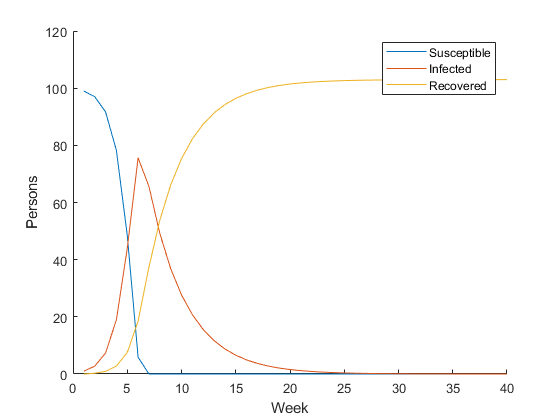

% Run simulation
[S, I, R, W] = sir_simulate(s_0, i_0, r_0, beta, gamma, 40);

% Plot
figure(1); clf; hold on;
plot(W, S); label1 = "Susceptible";
plot(W, I); label2 = "Infected";
plot(W, R); label3 = "Recovered";

xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})

**Exercise:** What would happen if you *decrease* $\beta$? Make a hypothesis about the resulting curves of S, I, and R. Then change $\beta$ to a lower value (say 1/4th its present value) and run the model again. Did your hypothesis hold?

## Looking Forward

In the next notebook we'll use this SIR model in conjunction with *data* to *choose parameters*. This will help us to better anchor our model in reality.